# **Matlab案例代码解析**

## 1. 基础函数使用案例

### 1.3 知乎提问

#### 1.3.1 Matlab如何将绘图保存为视频？

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/525069823/answer/2422969483](https://www.zhihu.com/question/525069823/answer/2422969483)

# Matlab如何将绘图保存为视频？

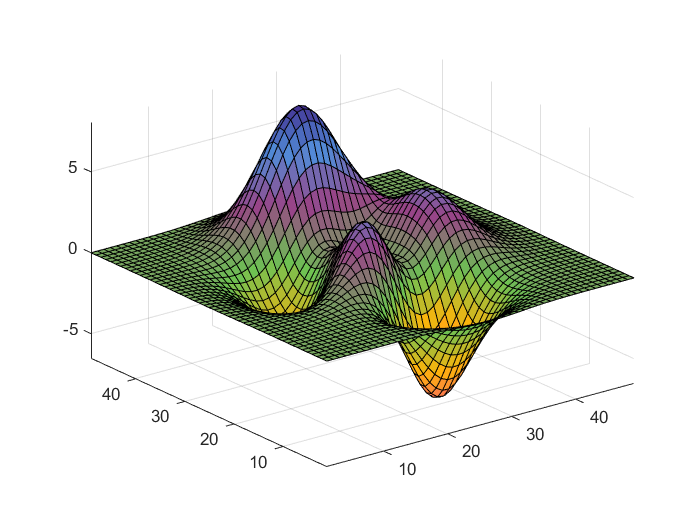

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 创建一个colormap
map = GenColormap(all_themes{1});

Z = peaks;
surf(Z); 
colormap(map);
axis tight manual 

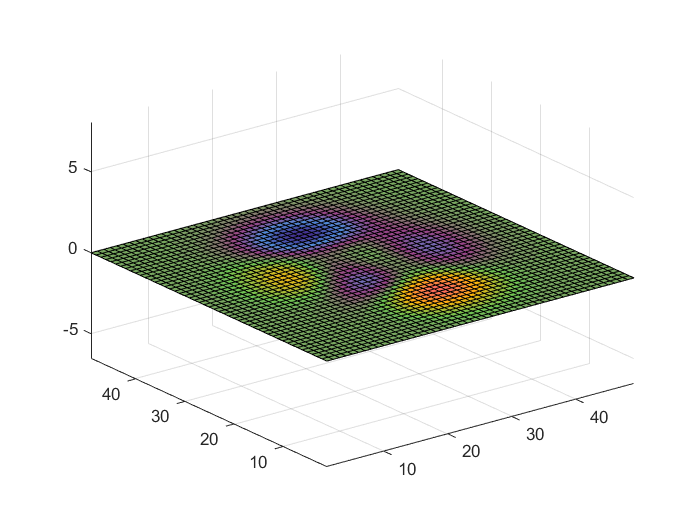

set(gca, 'nextplot','replacechildren'); 
v = VideoWriter('data\peaks.avi');
open(v);

for k = 1:20 
   surf(sin(2*pi*k/20)*Z,Z)
   frame = getframe(gcf);
   writeVideo(v,frame);
end

close(v);